Plot generator torque (Mgen) and aerodinamic torque (Maero) vs time.

disp('Plot generator torque (Mgen) and aerodinamic torque (Maero) vs time.')

Plot generator torque (Mgen) and aerodinamic torque (Maero) vs time.


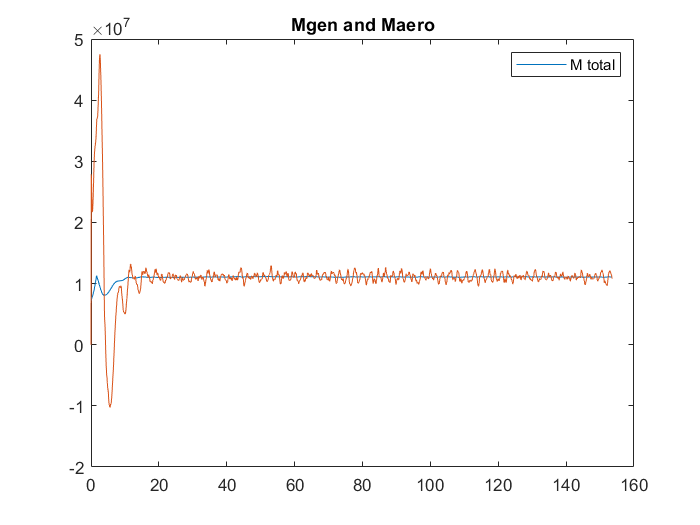

figure(2)

plot(time, Mgen_vec) 
legend('M gen')
hold on
plot(time, M_total) 
legend('M total')
hold off

title('Mgen and Maero')

Plot rotational velocity (omega) vs time.

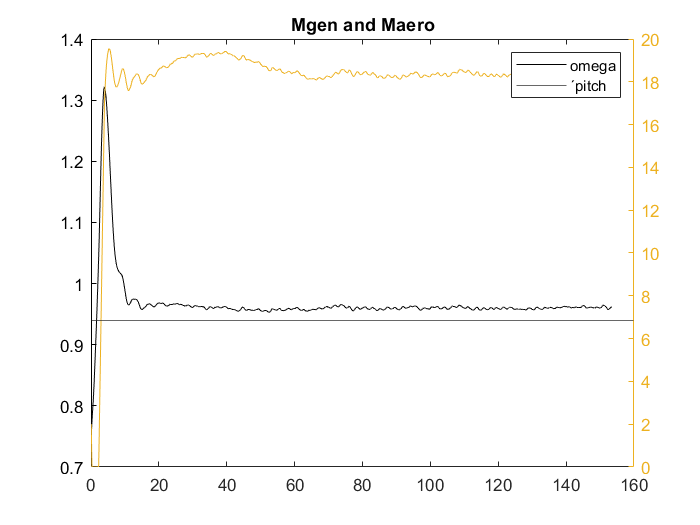

if length(omega) == length(time)
  
    plot(time, omega(1:end), time, rad2deg(pitch(1:end)))
    legend('omega', 'pitch')

elseif  length(omega) - 1 == length(time)
    figure(1)
    yyaxis left 
    plot(time, omega(1:end-1))
    
    yline(0.94)
    yyaxis right
    plot(time, rad2deg(pitch(1:end-1)))
    legend('omega','´pitch')
    
    
else
    disp('check the size of omega and time vector')
end